clear all;
clc;

# Autoencoders for Wireless Communications

## Training & Simulation Parameters

Set BLER simulation parameters.

simParams.EbNoVec = -2:0.5:8;
simParams.MinNumErrors = 10;
simParams.MaxNumFrames = 300;
simParams.NumSymbolsPerFrame = 10000;
simParams.SignalPower = 1;

## Train (2,2) Autoencoder with Energy Normalization

### **1. Train (2,2) Autoencoder**

Train a (2,2) autoencoder with energy normalization. Set training $E_b/N_o$ to 3 dB.

Train the autoencoder with an *Eb*/*No* value that is low enough to result in some errors but not too low such that the training algorithm cannot extract any useful information from the received symbols, y. Set *Eb*/*No* to 3 dB.

n = 2;                      % number of channel uses
k = 2;                      % number of input bits
EbNo = 3;                   % dB
normalization = "Energy";   % Normalization "Energy" | "Average power"

[txNet(1),rxNet(1),infoTemp,trainedNet(1)] = TrainWirelessAutoencoder(n,k,normalization,EbNo);
infoTemp.n = n;
infoTemp.k = k;
infoTemp.EbNo = EbNo;
infoTemp.Normalization = normalization;
info = infoTemp;


Plot constellation. For all M possible input symbols, get the output of the normalization layer. Map the real samples to complex samples by using odd samples as real part (in-phase) and even samples as imaginary part (quadrature). Also, plot t-SNE embedding constellation.

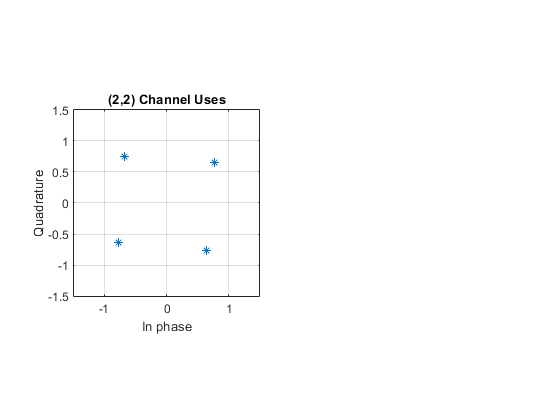

figure
subplot(1,2,1)
helperAEWPlotConstellation(trainedNet(1))

Plot the training progress. The validation accuracy quickly reaches more than 90% while the validation loss keeps slowly decreasing. This behavior shows that the training *E**b*/*N**o* value was low enough to cause some errors but not too low to avoid convergence.

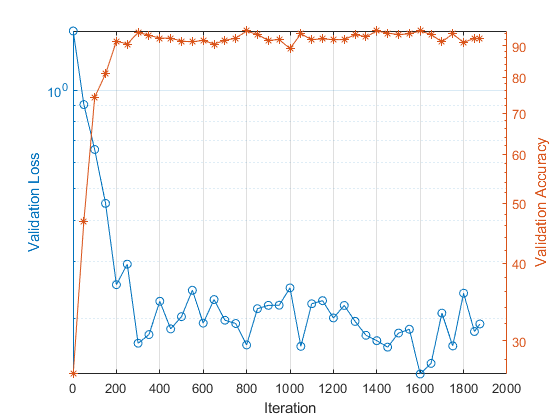

figure
validLoss = info.ValidationLoss;
idx = find(~isnan(validLoss));
yyaxis left; semilogy(idx, validLoss(idx), 'o-')
ylabel('Validation Loss')
validAcc = info.ValidationAccuracy;
idx = find(~isnan(validAcc));
yyaxis right; semilogy(idx, validAcc(idx), '*-')
ylabel('Validation Accuracy')
grid on
xlabel('Iteration')

### **2. Simulate the BLER performance comparing Trained (2,2) Autoencoder & (2,2) Theoretical Uncoded QPSK**

simParams.SignalPower = 1;
simParams.EbNoVec = 0:0.5:10

simParams = struct with fields:
               EbNoVec: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10]
          MinNumErrors: 10
          MaxNumFrames: 300
    NumSymbolsPerFrame: 10000
           SignalPower: 1


disp(simParams)

               EbNoVec: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10]
          MinNumErrors: 10
          MaxNumFrames: 300
    NumSymbolsPerFrame: 10000
           SignalPower: 1



ae22eBLER = helperAEWAutoencoderBLER(txNet(1),rxNet(1),simParams)

ae22eBLER =     0.1559    0.1366    0.1122    0.0945    0.0755    0.0614    0.0442    0.0322    0.0248    0.0157    0.0126    0.0079    0.0043    0.0029    0.0017    0.0016    0.0005    0.0002    0.0001    0.0000    0.0000


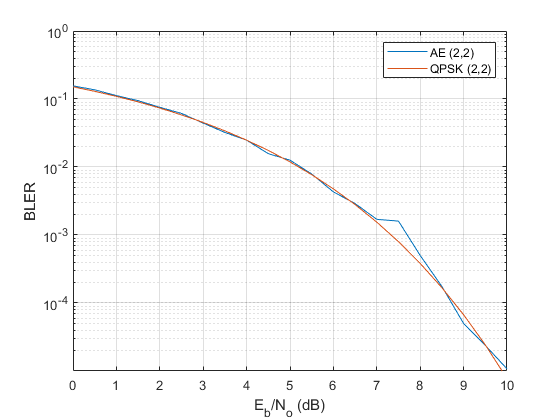

figure
semilogy(simParams.EbNoVec,ae22eBLER)
hold on
qpsk22BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^2;
semilogy(simParams.EbNoVec,qpsk22BLERTh)
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('AE (2,2)', 'QPSK (2,2)')

***The trained (2,2) autoencoder converges on a QPSK constellation with a phase shift as the optimal constellation for the channel conditions experienced.***

**INTUITION: **

Generate random integers representing k information bits. Use the helperAEWEncode function to encode these bits into complex symbols. The function runs the autoencoder's encoder, mapping the real-valued x vector to a complex x_c vector. In x_c, odd and even elements correspond to the in-phase and quadrature components of a complex symbol. Specifically, x_c = x(1:2:end) + j*x(2:2:end). Treat the x array as an interleaved complex array.

**Plot the autoencoder-learned constellation alongside the received constellation. In the case of a (2,2) configuration, the autoencoder learns a QPSK (M=2^k=4) constellation with a phase rotation.**

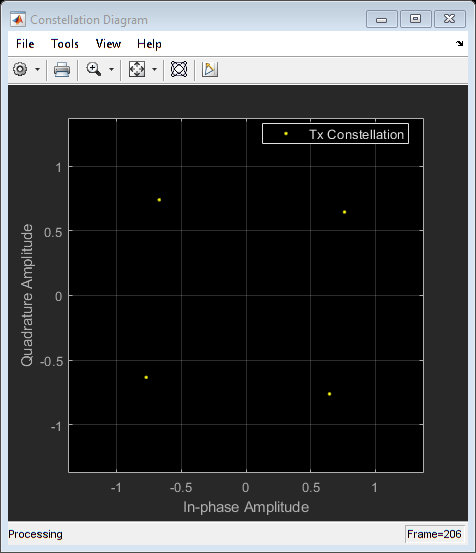

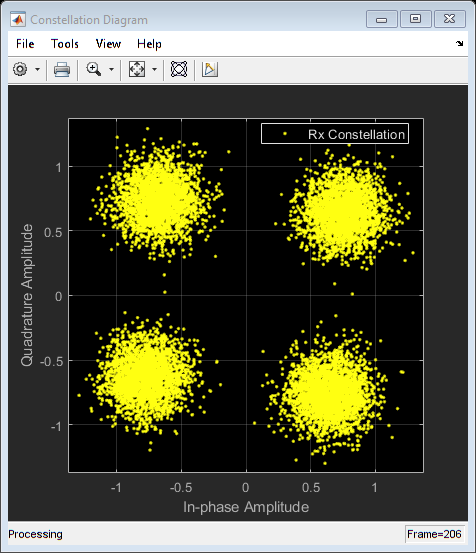

R = k/n;
EbNoChannelVec = simParams.EbNoVec + 10*log10(R);
M = 2^k;
txConst = comm.ConstellationDiagram(ShowReferenceConstellation=false, ...
  ShowLegend=true, ChannelNames={'Tx Constellation'});
rxConst = comm.ConstellationDiagram(ShowReferenceConstellation=false, ...
  ShowLegend=true, ChannelNames={'Rx Constellation'});
BLER = zeros(size(EbNoChannelVec));
%parfor trainingEbNoIdx = 1:length(EbNoChannelVec)
for trainingEbNoIdx = 1:length(EbNoChannelVec)
  EbNo = EbNoChannelVec(trainingEbNoIdx);
  chan = comm.AWGNChannel("BitsPerSymbol",2, ...
    "EbNo", EbNo, "SamplesPerSymbol", 1, "SignalPower", 1);

  numBlockErrors = 0;
  frameCnt = 0;
  while (numBlockErrors < simParams.MinNumErrors) ...
      && (frameCnt < simParams.MaxNumFrames)

    d = randi([0 M-1],simParams.NumSymbolsPerFrame,1);    % Random information bits
    x = helperAEWEncode(d,txNet(1));                      % Encoder
    txConst(x)
    y = chan(x);                                          % Channel
    rxConst(y)
    dHat = helperAEWDecode(y,rxNet(1));                   % Decoder

    numBlockErrors = numBlockErrors + sum(d ~= dHat);
    frameCnt = frameCnt + 1;
  end
  BLER(trainingEbNoIdx) = numBlockErrors / (frameCnt*simParams.NumSymbolsPerFrame);
end

## Train (2,4) Autoencoder with Energy Normalization

### **1. Train (2,4) Autoencoder**

Train a (2,4) autoencoder with energy normalization. Set training $E_b/N_o$ to 3 dB.

n = 2;
k = 4;
normalization = 'Energy';
EbNo = 3;

trainParams.MiniBatchSize = 20*2^k;
[txNet(2),rxNet(2),infoTemp,trainedNet(2)] = TrainWirelessAutoencoder(n,k,normalization,EbNo);
infoTemp.n = n;
infoTemp.k = k;
infoTemp.EbNo = EbNo;
infoTemp.Normalization = normalization;
info = infoTemp;

Plot constellation. For all M possible input symbols, get the output of the normalization layer. Map the real samples to complex samples by using odd samples as real part (in-phase) and even samples as imaginary part (quadrature). Also, plot t-SNE embedding constellation.

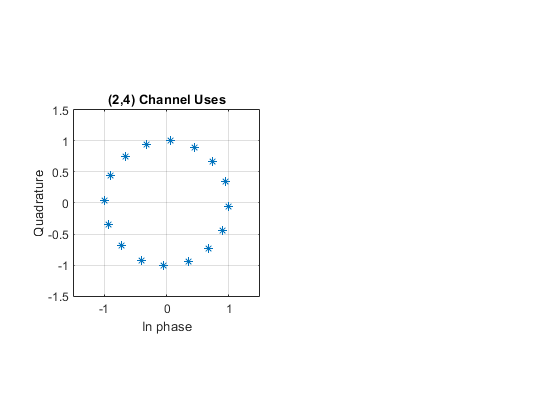

figure
subplot(1,2,1)
helperAEWPlotConstellation(trainedNet(2))

Plot training progress.

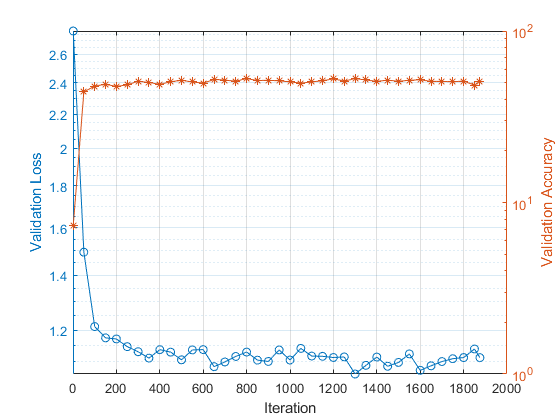

figure
validLoss = info.ValidationLoss;
idx = find(~isnan(validLoss));
yyaxis left; semilogy(idx, validLoss(idx), 'o-')
ylabel('Validation Loss')
validAcc = info.ValidationAccuracy;
idx = find(~isnan(validAcc));
yyaxis right; semilogy(idx, validAcc(idx), '*-')
ylabel('Validation Accuracy')
grid on
xlabel('Iteration')

### **2. Simulate the BLER performance comparing Trained (2,4) Autoencoder & (2,4) Theoretical Uncoded QPSK**

simParams.SignalPower = 1;
simParams.EbNoVec = 4:0.5:14;
ae24eBLER = helperAEWAutoencoderBLER(txNet(2),rxNet(2),simParams)

ae24eBLER =     0.3780    0.3580    0.3183    0.2986    0.2689    0.2493    0.2198    0.2006    0.1678    0.1433    0.1273    0.1031    0.0848    0.0736    0.0529    0.0422    0.0325    0.0248    0.0202    0.0118    0.0090


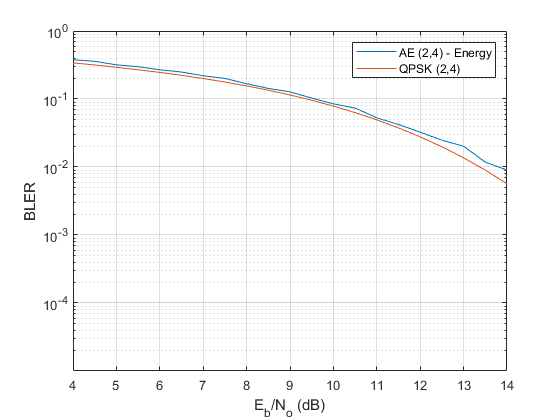


figure
semilogy(simParams.EbNoVec,ae24eBLER)
hold on
psk24BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',16,'nondiff')).^4;
semilogy(simParams.EbNoVec,psk24BLERTh)
% Calculate the theoretical BLER for 16-QAM
% qam16BLERTh = 1 - (1 - berawgn(simParams.EbNoVec, 'qam', 16,'nondiff')).^4;
% semilogy(simParams.EbNoVec,qam16BLERTh)
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('AE (2,4) - Energy', 'QPSK (2,4)')

## Train (2,4) Autoencoder with Average Power Normalization

### **1. Train (2,4) Autoencoder(**average power normalization**)**

Train a (2,2) autoencoder with average power normalization. Set training $E_b/N_o$ to 3 dB.

n = 2;
k = 4;
normalization = 'Average power';
EbNo = 3;

trainParams.MiniBatchSize = 20*2^k;
[txNet(3),rxNet(3),infoTemp,trainedNet(3)] = TrainWirelessAutoencoder(n,k,normalization,EbNo);
infoTemp.n = n;
infoTemp.k = k;
infoTemp.EbNo = EbNo;
infoTemp.Normalization = normalization;
info = infoTemp;

Plot constellation. For all M possible input symbols, get the output of the normalization layer. Map the real samples to complex samples by using odd samples as real part (in-phase) and even samples as imaginary part (quadrature). Also, plot t-SNE embedding constellation.

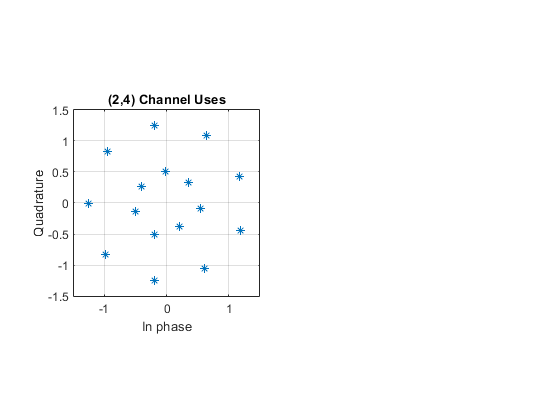

figure
subplot(1,2,1)
helperAEWPlotConstellation(trainedNet(3))

Plot training progress.

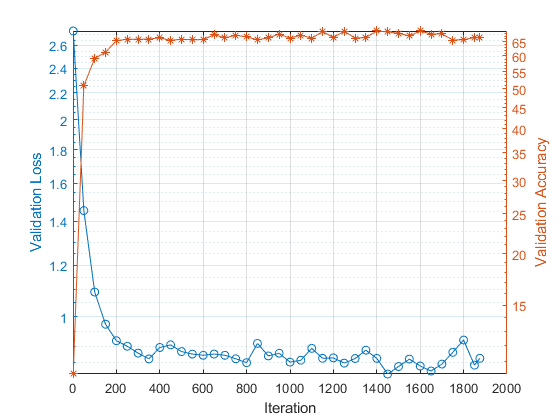

figure
validLoss = info.ValidationLoss;
idx = find(~isnan(validLoss));
yyaxis left; semilogy(idx, validLoss(idx), 'o-')
ylabel('Validation Loss')
validAcc = info.ValidationAccuracy;
idx = find(~isnan(validAcc));
yyaxis right; semilogy(idx, validAcc(idx), '*-')
ylabel('Validation Accuracy')
grid on
xlabel('Iteration')

### **2. Simulate the BLER performance comparing Trained (2,4) Autoencoder(**average power normalization**) & (2,2) Theoretical Uncoded QPSK**

simParams.SignalPower = 1;
simParams.EbNoVec = 0:0.5:10;
ae24pBLER = helperAEWAutoencoderBLER(txNet(3),rxNet(3),simParams)

ae24pBLER =     0.4579    0.4248    0.3949    0.3692    0.3369    0.2997    0.2799    0.2417    0.2087    0.1859    0.1643    0.1431    0.1185    0.1040    0.0876    0.0731    0.0584    0.0457    0.0376    0.0295    0.0237


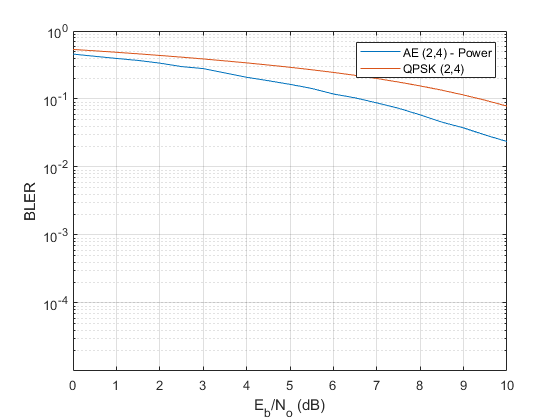

figure
semilogy(simParams.EbNoVec,ae24pBLER)
hold on
psk24BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',16,'nondiff')).^4;
semilogy(simParams.EbNoVec,psk24BLERTh)
% Calculate the theoretical BLER for 16-QAM
% qam16BLERTh = 1 - (1 - berawgn(simParams.EbNoVec, 'qam', 16,'nondiff')).^4;
% semilogy(simParams.EbNoVec,qam16BLERTh)
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('AE (2,4) - Power',  'QPSK (2,4)')

## Train (4,4) Autoencoder with Energy Normalization

### **1. Train (4,4) Autoencoder**

Train a (4,4) autoencoder with energy normalization. Set training $E_b/N_o$ to 3 dB.

n = 4;
k = 4;
normalization = 'Energy';
EbNo = 3;

trainParams.MiniBatchSize = 20*2^k;
[txNet(4),rxNet(4),infoTemp,trainedNet(4)] = TrainWirelessAutoencoder(n,k,normalization,EbNo);
infoTemp.n = n;
infoTemp.k = k;
infoTemp.EbNo = EbNo;
infoTemp.Normalization = normalization;
info = infoTemp;

Plot constellation. For all M possible input symbols, get the output of the normalization layer. Map the real samples to complex samples by using odd samples as real part (in-phase) and even samples as imaginary part (quadrature). Also, plot t-SNE embedding constellation.

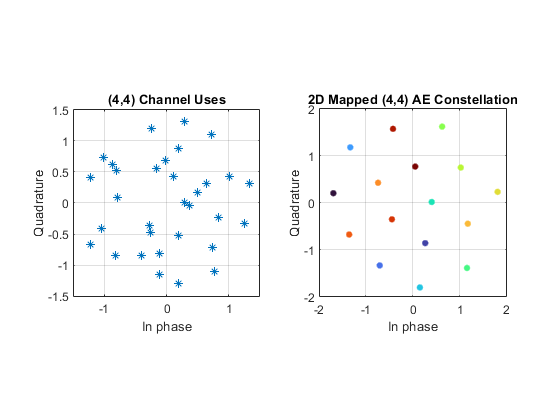

figure
subplot(1,2,1)
helperAEWPlotConstellation(trainedNet(4))
subplot(1,2,2)
helperAEWPlotConstellation(trainedNet(4),'t-sne')

Plot training progress.

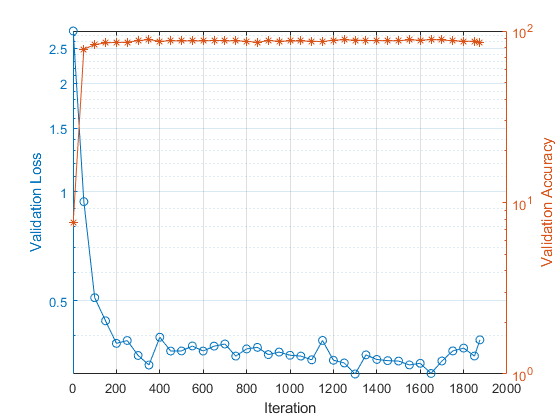

figure
validLoss = info.ValidationLoss;
idx = find(~isnan(validLoss));
yyaxis left; semilogy(idx, validLoss(idx), 'o-')
ylabel('Validation Loss')
validAcc = info.ValidationAccuracy;
idx = find(~isnan(validAcc));
yyaxis right; semilogy(idx, validAcc(idx), '*-')
ylabel('Validation Accuracy')
grid on
xlabel('Iteration')

### **2. Simulate the BLER performance comparing Trained (4,4) Autoencoder, (2,2) Theoretical Uncoded QPSK & (4,4) Theoretical Uncoded QPSK**

simParams.SignalPower = 1;
simParams.EbNoVec = 0:0.5:10

simParams = struct with fields:
               EbNoVec: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10]
          MinNumErrors: 10
          MaxNumFrames: 300
    NumSymbolsPerFrame: 10000
           SignalPower: 1


ae44eBLER = helperAEWAutoencoderBLER(txNet(4),rxNet(4),simParams)

ae44eBLER =     0.2561    0.2180    0.1840    0.1455    0.1181    0.0917    0.0712    0.0520    0.0397    0.0228    0.0144    0.0095    0.0061    0.0029    0.0014    0.0006    0.0003    0.0001    0.0000    0.0000    0.0000


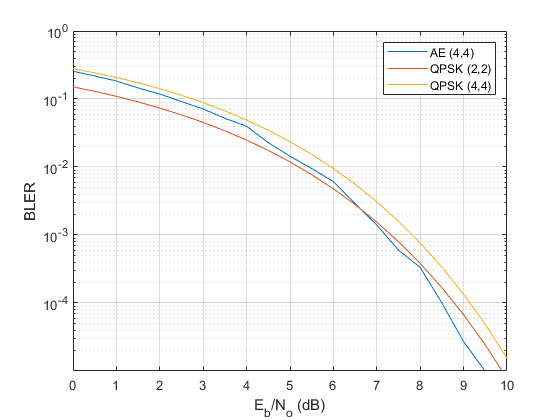

figure
semilogy(simParams.EbNoVec,ae44eBLER)
hold on
qpsk22BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^2;
semilogy(simParams.EbNoVec,qpsk22BLERTh)
qpsk44BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^4;
semilogy(simParams.EbNoVec,qpsk44BLERTh)
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('AE (4,4)', 'QPSK (2,2)', 'QPSK (4,4)')

## Train (8,8) Autoencoder with Energy Normalization

### **1. Train (8,8) Autoencoder**

Train a (8,8) autoencoder with energy normalization. Set training $E_b/N_o$ to 3 dB. Reduce the minibatch size to avoid running out of GPU memory.

n = 8;
k = 8;
normalization = 'Energy';
EbNo = 3;

trainParams.MiniBatchSize = 10*2^8;
[txNet(5),rxNet(5),infoTemp,trainedNet(5)] = TrainWirelessAutoencoder(n,k,normalization,EbNo);
infoTemp.n = n;
infoTemp.k = k;
infoTemp.EbNo = EbNo;
infoTemp.Normalization = normalization;
info = infoTemp;

Plot constellation. For all M possible input symbols, get the output of the normalization layer. Map the real samples to complex samples by using odd samples as real part (in-phase) and even samples as imaginary part (quadrature). Also, plot t-SNE embedding constellation.

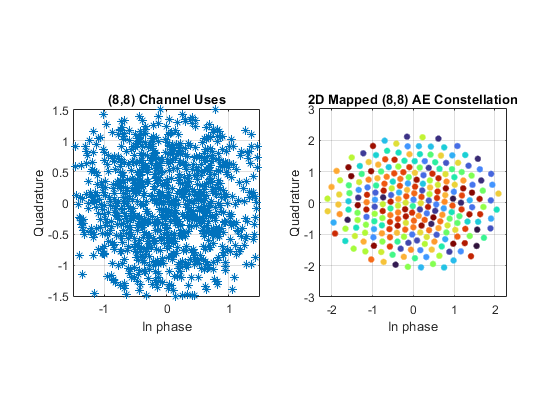

figure
subplot(1,2,1)
helperAEWPlotConstellation(trainedNet(5))
subplot(1,2,2)
helperAEWPlotConstellation(trainedNet(5),'t-sne')

Plot training progress.

figure
validLoss = info.ValidationLoss;

Unable to resolve the name info.ValidationLoss.

idx = find(~isnan(validLoss));
yyaxis left; semilogy(idx, validLoss(idx), 'o-')
ylabel('Validation Loss')
validAcc = info.ValidationAccuracy;
idx = find(~isnan(validAcc));
yyaxis right; semilogy(idx, validAcc(idx), '*-')
ylabel('Validation Accuracy')
grid on
xlabel('Iteration')


**2. Simulate the BLER performance comparing Trained (8,8) Autoencoder,  (2,2) Theoretical Uncoded QPSK & (8,8) Theoretical Uncoded QPSK**

simParams.SignalPower = 1;
simParams.EbNoVec = 0:0.5:10

simParams = struct with fields:
               EbNoVec: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10]
          MinNumErrors: 10
          MaxNumFrames: 300
    NumSymbolsPerFrame: 10000
           SignalPower: 1


ae88eBLER = helperAEWAutoencoderBLER(txNet(5),rxNet(5),simParams)

ae88eBLER =     0.3947    0.3349    0.2730    0.2238    0.1746    0.1300    0.0901    0.0602    0.0398    0.0248    0.0136    0.0074    0.0027    0.0015    0.0010    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000


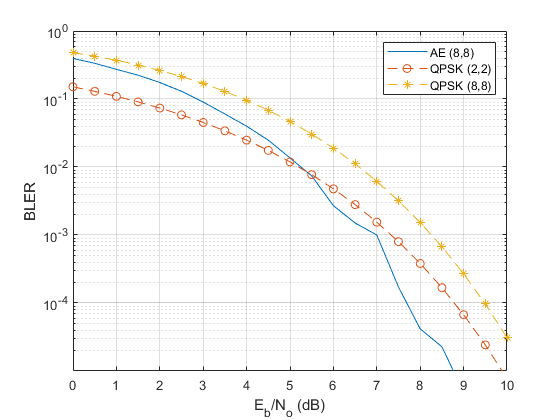

figure
semilogy(simParams.EbNoVec,ae88eBLER)
hold on
qpsk22BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^2;
semilogy(simParams.EbNoVec,qpsk22BLERTh,'--o')
qpsk88BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^8;
semilogy(simParams.EbNoVec,qpsk88BLERTh,'--*')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('AE (8,8)', 'QPSK (2,2)', 'QPSK (8,8)')

## Train (7,4) Autoencoder with Energy Normalization

### **1. Train (7,4) Autoencoder**

Train a (7,4) autoencoder with energy normalization. Set training $E_b/N_o$ to 3 dB.

n = 7;
k = 4;
normalization = 'Energy';
EbNo = 3;

trainParams.MiniBatchSize = 20*2^k;
[txNet(6),rxNet(6),infoTemp,trainedNet(6)] = TrainWirelessAutoencoder(n,k,normalization,EbNo);
infoTemp.n = n;
infoTemp.k = k;
infoTemp.EbNo = EbNo;
infoTemp.Normalization = normalization;
info = infoTemp;

Plot constellation. For all M possible input symbols, get the output of the normalization layer. Map the real samples to complex samples by using odd samples as real part (in-phase) and even samples as imaginary part (quadrature). Also, plot the t-SNE mapped 2-D constellation.

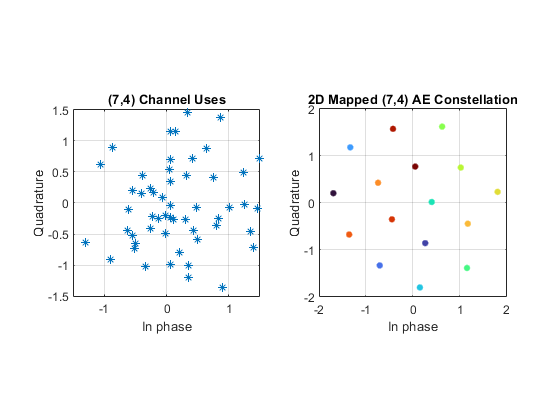

figure
subplot(1,2,1)
helperAEWPlotConstellation(trainedNet(6))
subplot(1,2,2)
helperAEWPlotConstellation(trainedNet(6),'t-sne')

Plot training progress.

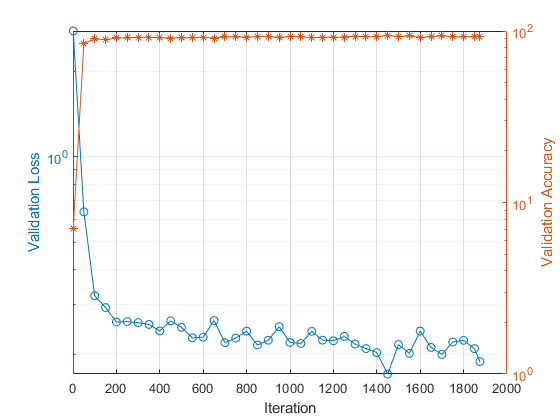

figure
validLoss = info.ValidationLoss;
idx = find(~isnan(validLoss));
yyaxis left; semilogy(idx, validLoss(idx), 'o-')
ylabel('Validation Loss')
validAcc = info.ValidationAccuracy;
idx = find(~isnan(validAcc));
yyaxis right; semilogy(idx, validAcc(idx), '*-')
ylabel('Validation Accuracy')
grid on
xlabel('Iteration')

### **2. Simulate the BLER performance comparing Trained (7,4) Autoencoder, (7,4) Hamming **hard decision decoding **& (7,4) Hamming ** maximum likelihood decoding

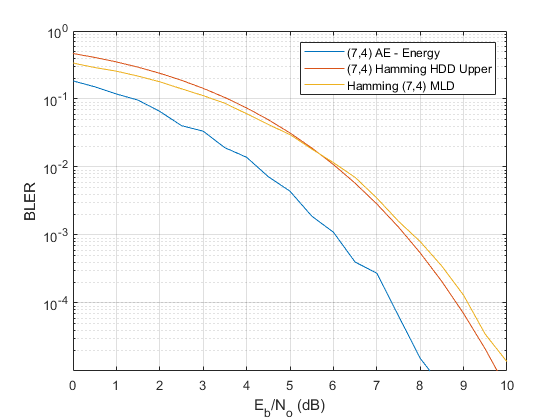

ae74eBLER = helperAEWAutoencoderBLER(txNet(6),rxNet(6),simParams);
berHamming = bercoding(simParams.EbNoVec,'hamming','hard',7);
blerHamming = 1-(1-berHamming).^7;
load codedBLERResults hammingML74BLER
figure
semilogy(simParams.EbNoVec,ae74eBLER)
hold on
semilogy(simParams.EbNoVec,blerHamming)
semilogy(simParams.EbNoVec,hammingML74BLER)
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('(7,4) AE - Energy', '(7,4) Hamming HDD Upper', 'Hamming (7,4) MLD')

# `Compare BLER Performance of Autoencoders with Coded and Uncoded QPSK(MAX_ERROR = 10)`

simulate the BLER performance of autoencoders with R=1 with that of uncoded QPSK systems. Use uncoded (2,2) and (8,8) QPSK as baselines. Compare BLER performance of these systems with that of (2,2), (4,4) and (8,8) autoencoders.

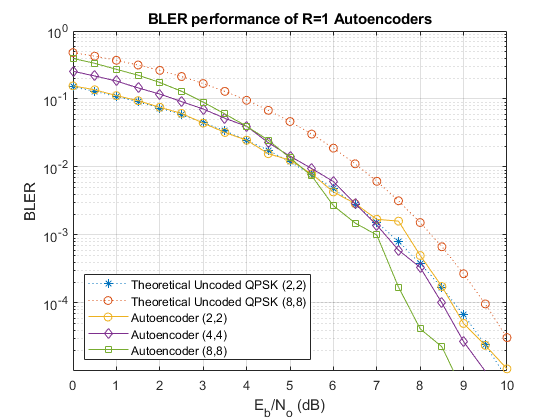


qpsk22BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^2;
semilogy(simParams.EbNoVec,qpsk22BLERTh,':*')
hold on
qpsk88BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^8;
semilogy(simParams.EbNoVec,qpsk88BLERTh,':o')
semilogy(simParams.EbNoVec,ae22eBLER,'-o')
semilogy(simParams.EbNoVec,ae44eBLER,'-d')
semilogy(simParams.EbNoVec,ae88eBLER,'-s')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Theoretical Uncoded QPSK (2,2)','Theoretical Uncoded QPSK (8,8)', ...
  'Autoencoder (2,2)','Autoencoder (4,4)','Autoencoder (8,8)','Location','southwest')
title('BLER performance of R=1 Autoencoders')

Simulate the BLER performance of a (7,4) autoencoder with that of (7,4) Hamming code with QPSK modulation for both hard decision and maximum likelihood (ML) decoding. Use uncoded (4,4) QPSK as a baseline. (4,4) uncoded QPSK is basically a QPSK modulated system that sends blocks of 4 bits and measures BLER. 

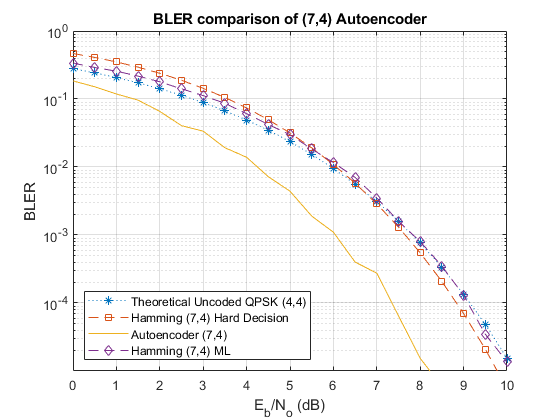

figure
qpsk44BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^4;
semilogy(simParams.EbNoVec,qpsk44BLERTh,':*')
hold on
semilogy(simParams.EbNoVec,blerHamming,'--s')
semilogy(simParams.EbNoVec,ae74eBLER,'-')
semilogy(simParams.EbNoVec,hammingML74BLER,'--d')

hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Theoretical Uncoded QPSK (4,4)','Hamming (7,4) Hard Decision', ...
  'Autoencoder (7,4)','Hamming (7,4) ML','Location','southwest')
title('BLER comparison of (7,4) Autoencoder')

# `Compare BLER Performance of Autoencoders with Coded and Uncoded QPSK(MAX_ERROR = 100)`

simulate the BLER performance of autoencoders with R=1 with that of uncoded QPSK systems. Use uncoded (2,2) and (8,8) QPSK as baselines. Compare BLER performance of these systems with that of (2,2), (4,4) and (8,8) autoencoders.

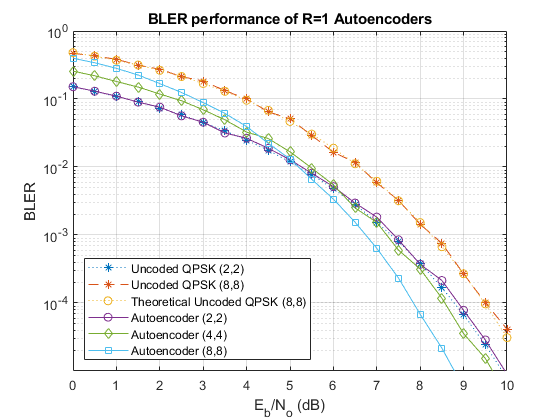

load uncodedBLERResults.mat
qpsk22BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^2;
semilogy(simParams.EbNoVec,qpsk22BLERTh,':*')
hold on
semilogy(simParams.EbNoVec,qpsk88BLER,'--*')
qpsk88BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^8;
semilogy(simParams.EbNoVec,qpsk88BLERTh,':o')
semilogy(simParams.EbNoVec,ae22eBLER,'-o')
semilogy(simParams.EbNoVec,ae44eBLER,'-d')
semilogy(simParams.EbNoVec,ae88eBLER,'-s')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Uncoded QPSK (2,2)','Uncoded QPSK (8,8)','Theoretical Uncoded QPSK (8,8)', ...
  'Autoencoder (2,2)','Autoencoder (4,4)','Autoencoder (8,8)','Location','southwest')
title('BLER performance of R=1 Autoencoders')

*While the Bit Error Rate (BER) remains constant for QPSK in both (8,8) and (2,2) cases, the Block Error Rate (BLER) is influenced by the block length, worsening as n increases according to BLER=1−(1−BER)^n. As anticipated, the BLER performance of (8,8) QPSK is inferior to the (2,2) QPSK system. The (2,2) autoencoder mirrors the BLER performance of (2,2) QPSK. In contrast, (4,4) and (8,8) autoencoders optimize both channel coding and constellation, yielding a coding gain over corresponding uncoded QPSK systems.*

Simulate the BLER performance of a (7,4) autoencoder with that of (7,4) Hamming code with QPSK modulation for both hard decision and maximum likelihood (ML) decoding. Use uncoded (4,4) QPSK as a baseline. (4,4) uncoded QPSK is basically a QPSK modulated system that sends blocks of 4 bits and measures BLER. 

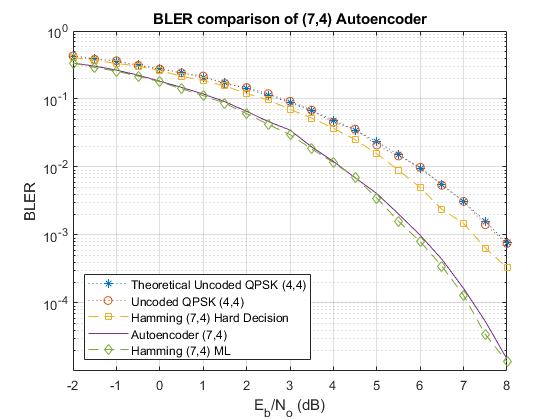

load codedBLERResults.mat
figure
qpsk44BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^4;
semilogy(simParams.EbNoVec,qpsk44BLERTh,':*')
hold on
semilogy(simParams.EbNoVec,qpsk44BLER,':o')
semilogy(simParams.EbNoVec,hammingHard74BLER,'--s')
semilogy(simParams.EbNoVec,ae74eBLER,'-')
semilogy(simParams.EbNoVec,hammingML74BLER,'--d')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Theoretical Uncoded QPSK (4,4)','Uncoded QPSK (4,4)','Hamming (7,4) Hard Decision', ...
  'Autoencoder (7,4)','Hamming (7,4) ML','Location','southwest')
title('BLER comparison of (7,4) Autoencoder')

In the realm of digital communication systems, the quest for robust and efficient error correction techniques is pivotal to enhance data reliability. In this context, the evaluation of Block Error Rate (BLER) serves as a crucial metric for assessing the performance of various encoding and modulation schemes. A notable contender in this landscape is the (7,4) autoencoder, a sophisticated neural network architecture designed to learn both modulation and channel coding simultaneously.

The preliminary BLER calculations for the (7,4) autoencoder reveal a compelling advantage over alternative coded and uncoded modulation techniques, particularly under computational **constraints that limit the analysis to a maximum of 10 errors**. This initial assessment hints at the promising potential of the (7,4) autoencoder, showcasing its superiority.

However, a more comprehensive analysis unfolds when the BLER calculations are **extended to consider a maximum of 100 errors**. The (7,4) autoencoder emerges as a standout performer, outshining other methods. The hard decision (7,4) Hamming code with QPSK modulation, for instance, exhibits a commendable 0.6 dB Eb/No advantage over uncoded QPSK. Taking it a step further, the ML decoding of (7,4) Hamming code, coupled with QPSK modulation, delivers an additional 1.5 dB advantage, achieving a BLER of 10^(-3).

The true prowess of the (7,4) autoencoder becomes apparent as its BLER performance approaches that of ML decoding for the (7,4) Hamming code. This remarkable feat is accomplished with a training regimen that involves a 3 dB Eb/No. The nuanced capabilities of the autoencoder shine through, demonstrating its adeptness at not only learning modulation intricacies but also unraveling the complexities of channel coding. The outcome is a coding gain of about 2 dB, a testament to the (7,4) autoencoder's ability to seamlessly integrate modulation and coding strategies, ultimately pushing the boundaries of performance in digital communication systems

***The Block Error Rate (BLER) findings illustrate the capacity of autoencoders to autonomously acquire joint coding and modulation strategies. Remarkably, training an autoencoder with a coding rate (R) of 1 can yield a coding gain compared to conventional approaches. Additionally, the example underscores the impact of hyperparameters, specifically Eb/No, on BLER performance.***

###  Performance Evaluation of Uncoded QAM and Autoencoded (8,8) in a Communication System

This study investigates the Block Error Rate (BLER) performance of Uncoded Quadrature Amplitude Modulation (QAM) alongside an Autoencoder with an (8,8) code rate. The comparison extends to various uncoded modulation schemes, including 64-QAM, QPSK, and 16-QAM. By analyzing BLER against different signal-to-noise ratios, the research aims to assess how the Autoencoder enhances the reliability of communication in comparison to traditional uncoded modulation techniques. The findings contribute insights into the potential benefits of employing autoencoding schemes for robust and efficient data transmission in communication systems.

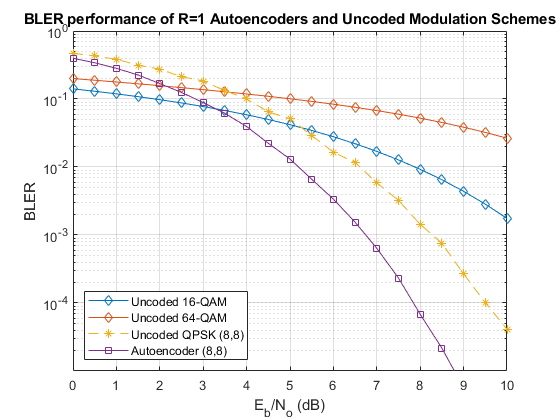

qam16BLERTh = berawgn(simParams.EbNoVec, 'qam', 16);
semilogy(simParams.EbNoVec, qam16BLERTh, '-d', 'DisplayName', 'Uncoded 16-QAM');
hold on

% Add lines for additional modulation schemes
qam16BLERTh = berawgn(simParams.EbNoVec, 'qam', 64);
semilogy(simParams.EbNoVec, qam16BLERTh, '-d', 'DisplayName', 'Uncoded 16-QAM');

semilogy(simParams.EbNoVec, qpsk88BLER, '--*')
semilogy(simParams.EbNoVec, ae88eBLER, '-s')
hold off

ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Uncoded 16-QAM', 'Uncoded 64-QAM', 'Uncoded QPSK (8,8)', ...
       'Autoencoder (8,8)', 'Location', 'southwest')
title('BLER performance of R=1 Autoencoders and Uncoded Modulation Schemes')

### Performance Comparison of (7,4) Autoencoder with Various Channel Coding Schemes

This comparison evaluates the Block Error Rate (BLER) performance of an (7,4) Autoencoder in the presence of different channel coding schemes. The Autoencoder is benchmarked against Reed-Solomon Coding (7,4). The simulation explores how these coding techniques impact the robustness of data transmission in a communication system. The results, presented in terms of BLER against varying signal-to-noise ratios, provide insights into the effectiveness of different coding strategies, aiding in the selection of the most suitable method for reliable data transmission in practical communication scenarios.

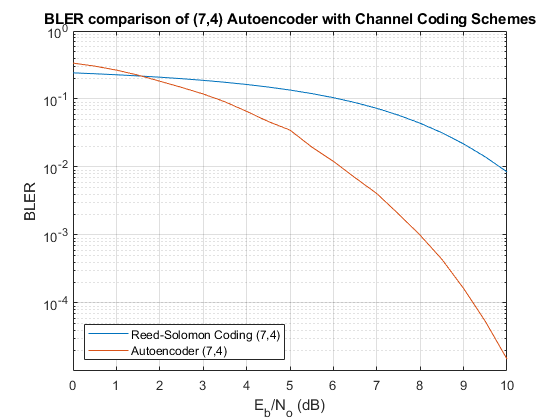

Simulation round 1/51


  1 

Unrecognized function or variable 'conv_encoder'.

Error in auto_encoder_2>turbo_encoder (line 586)
    code1 = conv_encoder(info_seq, transitions);

load uncodedBLERResults.mat
% Reed-Solomon Coding
rsCodingBLER = bercoding(simParams.EbNoVec, 'RS','hard',7,4,'qam',16);
semilogy(simParams.EbNoVec, rsCodingBLER, 'DisplayName', 'Reed-Solomon Coding');
hold on
semilogy(simParams.EbNoVec, ae74eBLER)
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend( 'Reed-Solomon Coding (7,4)', ...
        'Autoencoder (7,4)', 'Location', 'southwest')
title('BLER comparison of (7,4) Autoencoder with Channel Coding Schemes')

### Function for Calculate the BLER of Autoencoders

The function calculates the Block Error Rate (BLER) for trained autoencoders by simulating communication through an AWGN channel. It evaluates the performance based on a specified maximum error limit, offering insights into the robustness of the trained autoencoder.

function BLER = helperAEWAutoencoderBLER(txNet, rxNet, simParams)
    M = txNet.Layers(1).InputSize;
    k = log2(M);
    n = rxNet.Layers(1).InputSize;
    EbNoVec = simParams.EbNoVec;

    R = k / n;
    numSymbolsPerFrame = simParams.NumSymbolsPerFrame;
    BLER = zeros(size(EbNoVec));

    for EbNoIdx = 1:length(EbNoVec)
        EbNo = EbNoVec(EbNoIdx) + 10 * log10(R);
        chan = comm.AWGNChannel("BitsPerSymbol", 2, ...
            "EbNo", EbNo, "SamplesPerSymbol", 1, ...
            "SignalPower", simParams.SignalPower);

        numBlockErrors = 0;
        frameCnt = 0;

        while (numBlockErrors < simParams.MinNumErrors) ...
                && (frameCnt < simParams.MaxNumFrames)
            d = randi([0 M-1], numSymbolsPerFrame, 1);

            xComplex = helperAEWEncode(d, txNet);
            yComplex = chan(xComplex);
            dHat = helperAEWDecode(yComplex, rxNet);
            
            numBlockErrors = numBlockErrors + sum(d ~= dHat);
            frameCnt = frameCnt + 1;
        end

        BLER(EbNoIdx) = numBlockErrors / (frameCnt * numSymbolsPerFrame);
    end
end



### Function for Define and Train the Autoencoders

The function defines and trains an autoencoder for wireless communication, allowing it to learn efficient encoding and decoding strategies. It uses random data to simulate training and validation, providing a versatile tool for exploring joint coding and modulation schemes in communication systems.

function [txNet, rxNet, info, trainedNet] = TrainWirelessAutoencoder(n, k, normalization, EbNo, varargin)
    % Derived parameters
    M = 2^k;
    R = k/n;
    if nargin > 4
      trainParams = varargin{1};
    else
      trainParams.MaxEpochs = 15;
      trainParams.MiniBatchSize = 20*M;
      trainParams.InitialLearnRate = 0.01;
      trainParams.LearnRateSchedule = 'piecewise';
      trainParams.LearnRateDropPeriod = 10;
      trainParams.LearnRateDropFactor = 0.1;
      trainParams.Plots = 'none';
      trainParams.Verbose = false;
    end
    
    % Convert Eb/No to channel Eb/No values using the code rate
    EbNoChannel = EbNo + 10*log10(R);
    
    % As the number of possible input symbols increase, we need to increase the number of training symbols
    numTrainSymbols = 2500 * M;
    numValidationSymbols = 100 * M;
    
    % Define autoencoder network.
    wirelessAutoEncoder = [
        featureInputLayer(M, 'Name', 'One-hot input', 'Normalization', 'none')
        fullyConnectedLayer(M, 'Name', 'fc_1')
        reluLayer('Name', 'relu_1')
        fullyConnectedLayer(n, 'Name', 'fc_2')
        helperAEWNormalizationLayer('Method', normalization)
        
        helperAEWAWGNLayer('NoiseMethod', 'EbNo', 'EbNo', EbNoChannel, 'BitsPerSymbol', 2, 'SignalPower', 1)
        fullyConnectedLayer(M, 'Name', 'fc_3')
        reluLayer('Name', 'relu_2')
        fullyConnectedLayer(M, 'Name', 'fc_4')
        softmaxLayer('Name', 'softmax')
        classificationLayer('Name', 'classoutput')
    ];
    
    % Generate random training data. Create one-hot input vectors and labels. 
    d = randi([0 M-1],numTrainSymbols,1);
    trainSymbols = zeros(numTrainSymbols,M);
    trainSymbols(sub2ind([numTrainSymbols, M],...
      (1:numTrainSymbols)',d+1)) = 1;
    trainLabels = categorical(d);
    
    % Generate random validation data. Create one-hot input vectors and labels. 
    d = randi([0 M-1],numValidationSymbols,1);
    validationSymbols = zeros(numValidationSymbols,M);
    validationSymbols(sub2ind([numValidationSymbols, M],...
      (1:numValidationSymbols)',d+1)) = 1;
    validationLabels = categorical(d);

    % Set training options
    options = trainingOptions('adam', ...
      'InitialLearnRate',trainParams.InitialLearnRate, ...
      'MaxEpochs',trainParams.MaxEpochs, ...
      'MiniBatchSize',trainParams.MiniBatchSize, ...
      'Shuffle','every-epoch', ...
      'ValidationData',{validationSymbols,validationLabels}, ...
      'LearnRateSchedule', trainParams.LearnRateSchedule, ...
      'LearnRateDropPeriod', trainParams.LearnRateDropPeriod, ...
      'LearnRateDropFactor', trainParams.LearnRateDropFactor, ...
      'Plots', trainParams.Plots, ...
      'Verbose', trainParams.Verbose);

    % Train the autoencoder network
    [trainedNet,info] = trainNetwork(trainSymbols,trainLabels,wirelessAutoEncoder,options);
    
    % Separate the network into encoder and decoder parts. Encoder starts with
    % the input layer and ends after the normalization layer.    
    for idxNorm = 1:length(trainedNet.Layers)
      if isa(trainedNet.Layers(idxNorm), 'helperAEWNormalizationLayer')
        break
      end
    end
    lgraph = addLayers(layerGraph(trainedNet.Layers(1:idxNorm)), regressionLayer('Name', 'txout'));
    lgraph = connectLayers(lgraph, 'wnorm', 'txout');
    txNet = assembleNetwork(lgraph);
    
    % Decoder starts after the channel layer and ends with the classification
    % layer. Add a feature input layer at the beginning. 
    for idxChan = idxNorm:length(trainedNet.Layers)
      if isa(trainedNet.Layers(idxChan), 'helperAEWAWGNLayer')
        break
      end
    end
    firstLayerName = trainedNet.Layers(idxChan+1).Name;
    n = trainedNet.Layers(idxChan+1).InputSize;
    lgraph = addLayers(layerGraph(featureInputLayer(n, 'Name', 'rxin')), trainedNet.Layers(idxChan+1:end));
    lgraph = connectLayers(lgraph, 'rxin', firstLayerName);
    rxNet = assembleNetwork(lgraph);
end